# Sistema Beamformer

close all
clear variables
clc


### Modelo

delay = 0.5;
tao = 0.01*10;
k = 12.16;

ts = 0.01; % Periodo de muestreo de la simulación [s]
T = ts;

num = k;
den = [tao 1];

Gd = tf(num,den,'InputDelay',delay)

Gd =
 
                  12.16
  exp(-0.5*s) * ---------
                0.1 s + 1
 
Continuous-time transfer function.




sys1 = ss(Gd)

sys1 =
 
  A = 
        x1
   x1  -10
 
  B = 
       u1
   x1   8
 
  C = 
         x1
   y1  15.2
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 0.5 
 
Continuous-time state-space model.



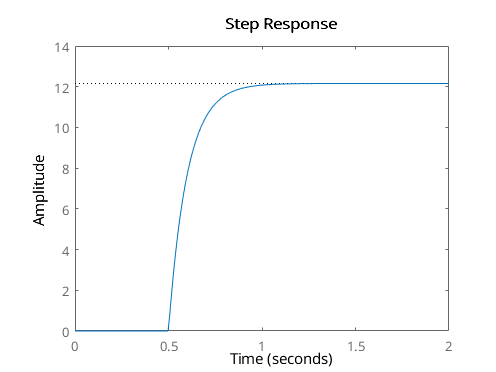

step(sys1)

### Espacio de estados

A = -1/tao;
B = k/tao;
C = 1;
D = 0;
Aa = [A zeros(length(A),1);-C 0];
Ba = [B;0];

sys2 = ss(A,B,C,D,'InputDelay',delay)

sys2 =
 
  A = 
        x1
   x1  -10
 
  B = 
          u1
   x1  121.6
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 0.5 
 
Continuous-time state-space model.



step(sys2)

### Espacio  de estados aumentado

tao1 = tao;
tao2 = tao*0.9;
A2 = diag([-1/tao1 -1/tao2]);
B2 = diag([k/tao1 k/tao2]);
C2 = eye(2);
C2a = [1/2 1/2];
D2 = zeros(1,2);
[A2 zeros(length(A2),2)]

ans =   -10.0000         0         0         0
         0  -11.1111         0         0


[-C2 zeros(2,2)]

ans =     -1     0     0     0
     0    -1     0     0


Aa2 = [A2 zeros(length(A2),1);-C2a 0]

Aa2 =   -10.0000         0         0
         0  -11.1111         0
   -0.5000   -0.5000         0


Ba2 = [B2;zeros(1,2)]

Ba2 =   121.6000         0
         0  135.1111
         0         0



sys3 = ss(A2,B2,C2a,D2,'InputDelay',delay)

sys3 =
 
  A = 
           x1      x2
   x1     -10       0
   x2       0  -11.11
 
  B = 
          u1     u2
   x1  121.6      0
   x2      0  135.1
 
  C = 
        x1   x2
   y1  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
 
  Input delays (seconds): 0.5  0.5 
 
Continuous-time state-space model.




obsv(A2,C2a)

ans =     0.5000    0.5000
   -5.0000   -5.5556


rank(obsv(A2,C2a))

ans = 2

### Observador

## **Calculo de polos deseados**

MP = 0.001; % maximo sobrepaso
ts = 4*tao; % Tiempo de establecimiento 
zheta = sqrt(log(MP)^2/(pi^2 + log(MP)^2));
Wn = 4/(ts*zheta);
s = tf('s');
P = s^2+2*zheta*Wn*s+Wn^2; % Polinomio Caracteristico deseado
G = Wn^2/P; % Funcion de transferencia
PolosO = pole(G);
PolosOd = exp(T*PolosO);

## Calculo de Constantes Observador

L = (acker(A2',C2a',[PolosO(1),PolosO(2)]))';
% L = L'

## Definir Observador

Ao = A2 - L*C2a;
Bo = [L B2];
Co = eye(2);
Do = zeros(2,3);

### Espacio de estados Discreto

discreteSys = c2d(sys2,T)

discreteSys =
 
  A = 
           x1
   x1  0.9048
 
  B = 
          u1
   x1  1.157
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
  Input delays (sampling periods): 50 
 
Sample time: 0.01 seconds
Discrete-time state-space model.



G = discreteSys.A

G = 0.9048

H = discreteSys.B

H = 1.1572

C = discreteSys.C

C = 1

D = discreteSys.D

D = 0


Ga = [G zeros(length(G),1); -C*G 1]

Ga =     0.9048         0
   -0.9048    1.0000


Ha = [H;-C*H]

Ha =     1.1572
   -1.1572


### Espacio de estados Discreto Aumentado

discreteSys = c2d(sys3,T)

discreteSys =
 
  A = 
           x1      x2
   x1  0.9048       0
   x2       0  0.8948
 
  B = 
          u1     u2
   x1  1.157      0
   x2      0  1.279
 
  C = 
        x1   x2
   y1  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
 
  Input delays (sampling periods): 50  50 
 
Sample time: 0.01 seconds
Discrete-time state-space model.



G2 = discreteSys.A

G2 =     0.9048         0
         0    0.8948


H2 = discreteSys.B

H2 =     1.1572         0
         0    1.2788


D2 = discreteSys.D

D2 =      0     0



G2a = [G2 zeros(length(G2),1); -C2a*G2 1]

G2a =     0.9048         0         0
         0    0.8948         0
   -0.4524   -0.4474    1.0000


H2a = [H2;-C2a*H2]

H2a =     1.1572         0
         0    1.2788
   -0.5786   -0.6394


## Calculo de Constantes Observador discreto

Ld = (acker(G2',C2a',PolosOd))';
% L = L'

## Definir Observador

Go = G2 - Ld*C2a;
Ho = [Ld H2];

## Control

## PID

K = 0.0066292;
Ti = 0.13485;
Td = 8.147e-5;

Kp = K - ((K*T)/(2*Ti));
Ki = (K*T)/Ti;
Kd = (K*Td)/T;

### LQR

Q = diag([0.001,0.003])

Q =     0.0010         0
         0    0.0030


R = 0.5;

Klqr = lqr(Aa,Ba,Q,R)

Klqr =     0.0179   -0.0775


### LQR 2 entradas

Q = diag([0.001 0.001 0.003])

Q =     0.0010         0         0
         0    0.0010         0
         0         0    0.0030


R = 0.5;

Klqr2 = lqr(Aa2,Ba2,Q,R)

Klqr2 =     0.0137    0.0021   -0.0546
    0.0023    0.0135   -0.0549


### LQR discreto

Q = diag([0.00001,0.00003])

Q = 1.0e-04 *

    0.1000         0
         0    0.3000


R = 70;

Kdlqr = dlqr(Ga,Ha,Q,R)

Kdlqr =     0.0060   -0.0007


### LQR discreto 2 entradas

Q = diag([0.00001,0.00001,0.00003])

Q = 1.0e-04 *

    0.1000         0         0
         0    0.1000         0
         0         0    0.3000


R = 70;

Kdlqr2 = dlqr(G2a,H2a,Q,R)

Kdlqr2 =     0.0021    0.0019   -0.0005
    0.0021    0.0019   -0.0005
